% Generated by MATLAB(R) 24.2 (R2024b) and 5G Toolbox 24.2 (R2024b).
% Generated on: 11-Feb-2025 02:19:23

## Generating Downlink FRC waveform

Downlink FRC configuration

cfgDLFRC = nrDLCarrierConfig;
cfgDLFRC.Label = 'DL-FRC-FR1-64QAM';
cfgDLFRC.FrequencyRange = 'FR1';
cfgDLFRC.ChannelBandwidth = 10;
cfgDLFRC.NCellID = 1;
cfgDLFRC.NumSubframes = 10;
cfgDLFRC.InitialNSubframe = 0;
cfgDLFRC.WindowingPercent = 0;
cfgDLFRC.SampleRate = [];
cfgDLFRC.CarrierFrequency = 0;

## SCS specific carriers

scscarrier = nrSCSCarrierConfig;
scscarrier.SubcarrierSpacing = 15;
scscarrier.NSizeGrid = 52;
scscarrier.NStartGrid = 0;

cfgDLFRC.SCSCarriers = {scscarrier};

## Bandwidth Parts

bwp = nrWavegenBWPConfig;
bwp.BandwidthPartID = 1;
bwp.Label = 'BWP1';
bwp.SubcarrierSpacing = 15;
bwp.CyclicPrefix = 'normal';
bwp.NSizeBWP = 52;
bwp.NStartBWP = 0;

cfgDLFRC.BandwidthParts = {bwp};

## Synchronization Signals Burst

ssburst = nrWavegenSSBurstConfig;
ssburst.Enable = true;
ssburst.Power = 0;
ssburst.BlockPattern = 'Case A';
ssburst.TransmittedBlocks = [1 0 0 0];
ssburst.Period = 10;
ssburst.NCRBSSB = [];
ssburst.KSSB = 0;
ssburst.DataSource = 'MIB';
ssburst.DMRSTypeAPosition = 2;
ssburst.CellBarred = false;
ssburst.IntraFreqReselection = false;
ssburst.PDCCHConfigSIB1 = 0;
ssburst.SubcarrierSpacingCommon = 30;

cfgDLFRC.SSBurst = ssburst;

## CORESET and Search Space Configuration

coreset = nrCORESETConfig;
coreset.CORESETID = 1;
coreset.Label = 'CORESET1';
coreset.FrequencyResources = ones([1 8]);
coreset.Duration = 2;
coreset.CCEREGMapping = 'noninterleaved';
coreset.REGBundleSize = 6;
coreset.InterleaverSize = 2;
coreset.ShiftIndex = 0;
coreset.PrecoderGranularity = 'sameAsREG-bundle';
coreset.RBOffset = [];

cfgDLFRC.CORESET = {coreset};

% Search Spaces
searchspace = nrSearchSpaceConfig;
searchspace.SearchSpaceID = 1;
searchspace.Label = 'SearchSpace1';
searchspace.CORESETID = 1;
searchspace.SearchSpaceType = 'common';
searchspace.StartSymbolWithinSlot = 0;
searchspace.SlotPeriodAndOffset = [1 0];
searchspace.Duration = 1;
searchspace.NumCandidates = [8 8 4 2 1];

cfgDLFRC.SearchSpaces = {searchspace};

## PDCCH Instances Configuration

pdcch = nrWavegenPDCCHConfig;
pdcch.Enable = false;
pdcch.Label = 'PDCCH1';
pdcch.Power = 0;
pdcch.BandwidthPartID = 1;
pdcch.SearchSpaceID = 1;
pdcch.AggregationLevel = 1;
pdcch.AllocatedCandidate = 1;
pdcch.CCEOffset = [];
pdcch.SlotAllocation = 1:9;
pdcch.Period = 10;
pdcch.Coding = false;
pdcch.DataBlockSize = 20;
pdcch.DataSource = 0;
pdcch.RNTI = 0;
pdcch.DMRSScramblingID = 1;
pdcch.DMRSPower = 0;

cfgDLFRC.PDCCH = {pdcch};

## PDSCH Instances Configuration

pdsch = nrWavegenPDSCHConfig;
pdsch.Enable = true;
pdsch.Label = 'Full-band PDSCH sequence';
pdsch.Power = 0;
pdsch.BandwidthPartID = 1;
pdsch.Modulation = '64QAM';
pdsch.NumLayers = 1;
pdsch.MappingType = 'A';
pdsch.ReservedCORESET = [];
pdsch.SymbolAllocation = [2 12];
pdsch.SlotAllocation = 1:9;
pdsch.Period = 10;
pdsch.PRBSet = 0:51;
pdsch.PRBSetType = 'VRB';
pdsch.VRBToPRBInterleaving = false;
pdsch.VRBBundleSize = 2;
pdsch.NID = [];
pdsch.RNTI = 0;
pdsch.Coding = true;
pdsch.TargetCodeRate = 0.75390625;
pdsch.TBScaling = 1;
pdsch.XOverhead = 0;
pdsch.LimitedBufferRateMatching = true;
pdsch.MaxNumLayers = 8;
pdsch.MCSTable = 'qam64';
pdsch.RVSequence = 0;
pdsch.DataSource = 'PN9';
pdsch.DMRSPower = 3;
pdsch.EnablePTRS = false;
pdsch.PTRSPower = 0;

% PDSCH Reserved PRB
pdschReservedPRB = nrPDSCHReservedConfig;
pdschReservedPRB.PRBSet = [];
pdschReservedPRB.SymbolSet = [];
pdschReservedPRB.Period = [];

pdsch.ReservedPRB = {pdschReservedPRB};

% PDSCH DM-RS
pdschDMRS = nrPDSCHDMRSConfig;
pdschDMRS.DMRSConfigurationType = 1;
pdschDMRS.DMRSReferencePoint = 'CRB0';
pdschDMRS.DMRSTypeAPosition = 2;
pdschDMRS.DMRSAdditionalPosition = 2;
pdschDMRS.DMRSLength = 1;
pdschDMRS.CustomSymbolSet = [];
pdschDMRS.DMRSPortSet = [];
pdschDMRS.NIDNSCID = [];
pdschDMRS.NSCID = 0;
pdschDMRS.NumCDMGroupsWithoutData = 2;
pdschDMRS.DMRSDownlinkR16 = false;
pdschDMRS.DMRSEnhancedR18 = false;

pdsch.DMRS = pdschDMRS;

% PDSCH PT-RS
pdschPTRS = nrPDSCHPTRSConfig;
pdschPTRS.TimeDensity = 1;
pdschPTRS.FrequencyDensity = 2;
pdschPTRS.REOffset = '00';
pdschPTRS.PTRSPortSet = [];

pdsch.PTRS = pdschPTRS;

cfgDLFRC.PDSCH = {pdsch};

## CSI-RS Instances Configuration

csirs = nrWavegenCSIRSConfig;
csirs.Enable = false;
csirs.Label = 'CSIRS1';
csirs.Power = 0;
csirs.BandwidthPartID = 1;
csirs.CSIRSType = 'nzp';
csirs.CSIRSPeriod = 'on';
csirs.RowNumber = 3;
csirs.Density = 'one';
csirs.SymbolLocations = 0;
csirs.SubcarrierLocations = 0;
csirs.NumRB = 52;
csirs.RBOffset = 0;
csirs.NID = 1;

cfgDLFRC.CSIRS = {csirs};

% Generation
[waveform,info] = nrWaveformGenerator(cfgDLFRC);

Fs = info.ResourceGrids(1).Info.SampleRate; 								 % Specify the sample rate of the waveform in Hz

## Visualize

Spectrum Analyzer

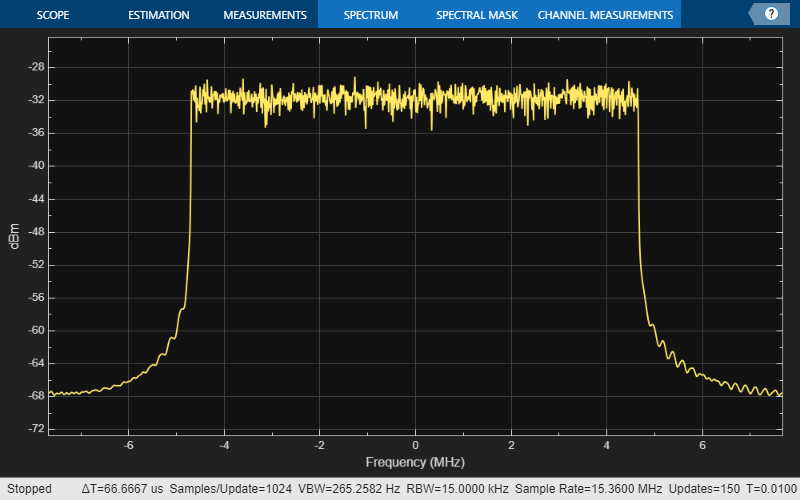

spectrum = spectrumAnalyzer('SampleRate', Fs);
spectrum(waveform);
release(spectrum);

## Constellation

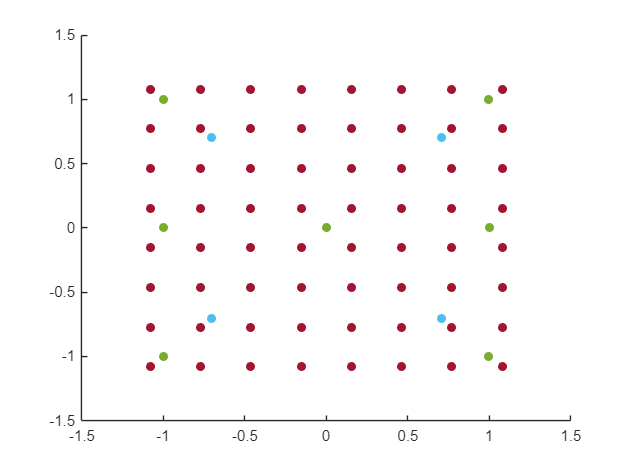

ofdm_grid = nrOFDMDemodulate(nrCarrierConfig,waveform);
scatter(real(ofdm_grid), imag(ofdm_grid), "filled")

## Params

masterclkrate = 100e6;
interpdecim = 6;
numsamps = length(waveform);

## Waveform Resample

newFs = 100e6/6;

[p,q] = rat(newFs/Fs,1e-7);

waveform = resample(waveform,p,q);

## SDR Setup

tx = comm.SDRuTransmitter("Platform","N200/N210/USRP2",...
    "CenterFrequency", 2.8e9, ...
    "ChannelMapping", 1,...
    "ClockSource","Internal",...
    "Gain",20, ...
    "MasterClockRate",masterclkrate)

tx =   comm.SDRuTransmitter with properties:

                 Platform: 'N200/N210/USRP2'
                IPAddress: '192.168.10.2'
           ChannelMapping: 1
          CenterFrequency: 2.8000e+09
    LocalOscillatorOffset: 0
                     Gain: 20
                PPSSource: 'Internal'
        EnableTimeTrigger: false
              ClockSource: 'Internal'
      EnableMIMOCableSync: false
          MasterClockRate: 100000000
      InterpolationFactor: 512
        TransportDataType: 'int16'
          EnableBurstMode: false


rx = comm.SDRuReceiver("Platform","N200/N210/USRP2",...
    "CenterFrequency",2.8e9,...
    "Gain",20,...
    "MasterClockRate",masterclkrate,...
    "OutputDataType", "double",...
    "SamplesPerFrame",numsamps)

rx =   comm.SDRuReceiver with properties:

                 Platform: 'N200/N210/USRP2'
                IPAddress: '192.168.10.2'
           ChannelMapping: 1
          CenterFrequency: 2.8000e+09
    LocalOscillatorOffset: 0
                     Gain: 20
                PPSSource: 'Internal'
        EnableTimeTrigger: false
              ClockSource: 'Internal'
      EnableMIMOCableSync: false
          MasterClockRate: 100000000
         DecimationFactor: 512
        TransportDataType: 'int16'
           OutputDataType: 'double'
          SamplesPerFrame: 153600
          EnableBurstMode: false


## Duration Setup

frametime = numsamps/Fs;
timespan = 30;
numframes = timespan/frametime

numframes = 3000

## Transmission

for i=1:numframes
    txdata = waveform
    underrun = tx(txData);
    if underrun~=0
        disp('Transmission successful')
    end
    % Receive the signal

    [rxdata, ~,overflow, rx_time_stamp] = rx();
    if overflow~=0
        disp('Reception successful')
    end
end

## Decimate the rx to std 5g Fs

[p,q] = rat(Fs/newFs,1e-7);
waveform = resample(waveform,p,q);

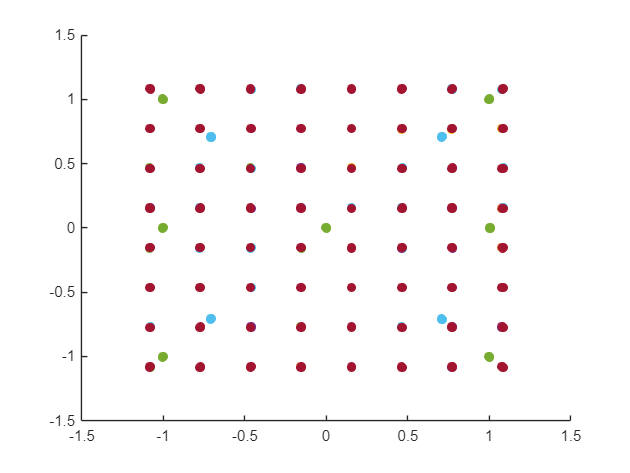

ofdm_grid = nrOFDMDemodulate(nrCarrierConfig,waveform);  % Change Waveform to rxdata
scatter(real(ofdm_grid), imag(ofdm_grid), "filled")